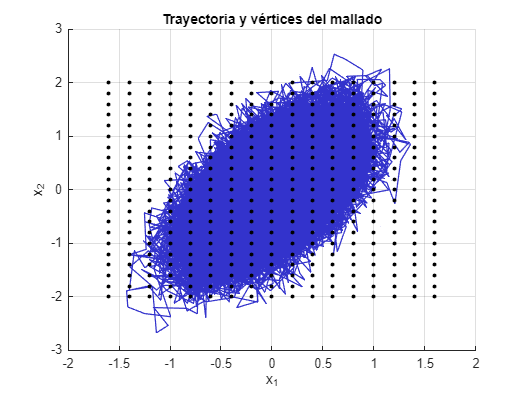

%% Parámetros del sistema
m = 1;
eta = 1;
T1 = 1;
T2 = 5;
k = 10;
x1_0 = 0;
x2_0 = 0;
tspan = [0, 1000];
dt = 0.01;
N = round((tspan(2)-tspan(1))/dt);
t = linspace(tspan(1), tspan(2), N);
kb = 1;
x1_eq = 0;
x2_eq = 0;

%% Simulación de x1 y x2 con ruido térmico
x1 = zeros(1, N);
x2 = zeros(1, N);
x1(1) = x1_0;
x2(1) = x2_0;
sqrt_term1 = sqrt(2 * kb * T1);
sqrt_term2 = sqrt(2 * kb * T2);

for n = 1:N-1
    dW1 = sqrt(dt) * randn;
    dW2 = sqrt(dt) * randn;
    x1(n+1) = x1(n) + ((-2*k*(x1(n)-x1_eq) + k*(x2(n)-x2_eq))/eta)*dt + (sqrt_term1/eta)*dW1;
    x2(n+1) = x2(n) + ((-2*k*(x2(n)-x2_eq) + k*(x1(n)-x1_eq))/eta)*dt + (sqrt_term2/eta)*dW2;
end

%% Definición del mallado
step_size = 0.2;
x_min = -1.6; x_max = 1.6;
y_min = -2.0; y_max = 2.0;
x_vals = x_min:step_size:x_max;
y_vals = y_min:step_size:y_max;
[Xg, Yg] = meshgrid(x_vals, y_vals);
xx1 = reshape(Xg, [], 1);
yy1 = reshape(Yg, [], 1);

%% FIGURA 1: Trayectoria + vértices del mallado
figure;
hold on; grid on;

% Trazo de la trayectoria
plot(x1, x2, 'Color', [0.2 0.2 0.8 0.2], 'LineWidth', 1);

% Vértices del mallado como puntos
scatter(Xg(:), Yg(:), 10, 'k', 'filled');

xlabel('x_1'); ylabel('x_2');
title('Trayectoria y vértices del mallado');

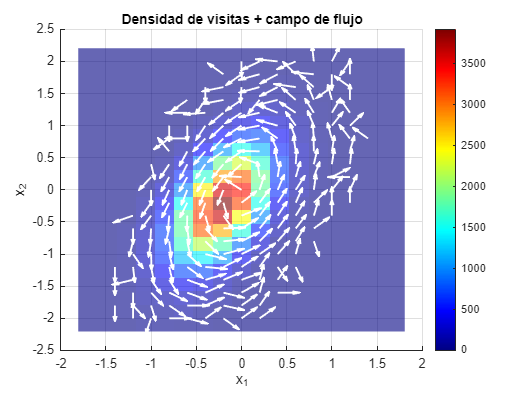


%% FIGURA 2: Mapa de calor + campo de flujo
figure;
hold on; grid on;

% Aproximación de posiciones a vértices del mallado
xy2 = [x1(:), x2(:)];
ixy = round(xy2 / step_size) * step_size;

% Transiciones
trans1 = ixy(1:end-1, :);
trans2 = ixy(2:end, :);
transvec = trans1 - trans2;
sal = [trans1, transvec];
ent = [trans2, transvec];
allpts = [sal; ent];

% Cálculo del campo de flujo en cada celda
tol = 1e-6;
flow = zeros(length(xx1), 4);
for k = 1:length(xx1)
    indx = find(abs(allpts(:,1) - xx1(k)) < tol);
    indy = find(abs(allpts(:,2) - yy1(k)) < tol);
    ind = intersect(indx, indy);
    if isempty(ind)
        sdx = 0; sdy = 0;
    else
        sdx = sum(allpts(ind,3));
        sdy = sum(allpts(ind,4));
    end
    flow(k,:) = [xx1(k), yy1(k), sdx, sdy];
end

% Normalización del campo
flowX = flow(:,3);
flowY = flow(:,4);
M = sqrt(flowX.^2 + flowY.^2);
M(M==0) = 1;
UX = flowX ./ M;
UY = flowY ./ M;

% Mapa de calor de visitas
nx = numel(x_vals);
ny = numel(y_vals);
ix = round((x1 - x_min) / step_size);
iy = round((x2 - y_min) / step_size);
valid = (ix >= 1 & ix <= nx & iy >= 1 & iy <= ny);
linIdx = sub2ind([nx, ny], ix(valid), iy(valid));
linIdx = linIdx(:);
transition_counts = accumarray(linIdx, 1, [nx*ny,1]);
transition_counts = reshape(transition_counts, [nx, ny]);

% Pintar mapa de calor
imagesc([x_min-step_size/2, x_max+step_size/2], ...
        [y_min-step_size/2, y_max+step_size/2], transition_counts');
set(gca, 'YDir', 'normal');
colormap(jet); colorbar; alpha(0.6);

% Añadir campo de flujo
quiver(xx1, yy1, UX*0.1, UY*0.1, ...
       'w', 'LineWidth', 1.5, 'MaxHeadSize', 2);

xlabel('x_1'); ylabel('x_2');
title('Densidad de visitas + campo de flujo');